# Track Generator

we input both x and y coordinates, the scripts then saves a interpolated and smoothed versioned of the provided path in a .mat file.

% number of points in the track
N_POINTS = 30

N_POINTS = 30


% time of arrival (no explict meaning in this case)
toa = 20  % seconds

toa = 20

% 2D points coordinates to be interpolated
ref_coords = [
    0, 0;
    1, 0;
    2, 0;
    3, 0;
    4, 0;
    5, 0.5;
    6, 1.5;
    6.5, 2.5;
    6.5, 3.5;
    6, 4.5;
    5, 5.5;
    4, 6;
    3, 6;
    2, 6;
    1, 6;
    0, 6;
]

ref_coords =          0         0
    1.0000         0
    2.0000         0
    3.0000         0
    4.0000         0
    5.0000    0.5000
    6.0000    1.5000
    6.5000    2.5000
    6.5000    3.5000
    6.0000    4.5000



ref_coords(:, 2) = ref_coords(:, 2) - 1500

% add third coordinate (all zeros)
ref_coords(:, 3) = zeros(length(ref_coords), 1)

ref_coords =          0         0         0
    1.0000         0         0
    2.0000         0         0
    3.0000         0         0
    4.0000         0         0
    5.0000    0.5000         0
    6.0000    1.5000         0
    6.5000    2.5000         0
    6.5000    3.5000         0
    6.0000    4.5000         0


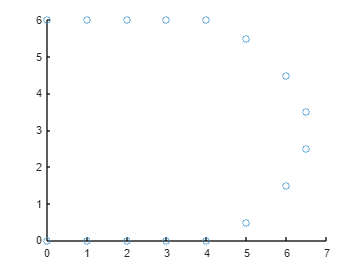


% visualization of the provided coordinates
scatter(ref_coords(:, 1), ref_coords(:, 2))

% create trajectory
trajectory = waypointTrajectory( ...
    ref_coords, ...
    linspace(0, toa, length(ref_coords)), ...
    SampleRate=1 ...
)

trajectory =   waypointTrajectory with properties:

         SampleRate: 1
    SamplesPerFrame: 1
          Waypoints: [16×3 double]
      TimeOfArrival: [16×1 double]
         Velocities: [16×3 double]
             Course: [16×1 double]
        GroundSpeed: [16×1 double]
          ClimbRate: [16×1 double]
        Orientation: [16×1 quaternion]
          AutoPitch: 0
           AutoBank: 0
     ReferenceFrame: 'NED'


trajectory.SampleRate = N_POINTS / toa;
reset(trajectory)

count = 1;
track_info = zeros(N_POINTS, 2)

track_info =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0



while ~isDone(trajectory)
   [current_position, current_orientation, ~] = trajectory();

   euler_orient = quat2eul(current_orientation)

   track_info(count, 1) = current_position(1)
   track_info(count, 2) = current_position(2)
   track_info(count, 3) = euler_orient(1)

   count = count + 1;
end

euler_orient = 1.0e-03 *

    0.4820         0         0


track_info =     0.5000         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


track_info =     0.5000    0.0007
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


track_info =     0.5000    0.0007    0.0005
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


euler_orient =    -0.0039         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


euler_orient =    -0.0024         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


euler_orient =     0.0135         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


euler_orient =     0.0092         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


euler_orient =    -0.0501         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
         0         0         0
         0         0         0
         0         0         0
         0         0         0


euler_orient =    -0.0360         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930         0         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295         0
         0         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
         0         0         0
         0         0         0
         0         0         0


euler_orient =     0.1875         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0         0
         0         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
         0         0         0
         0         0         0


euler_orient =     0.4757         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068         0         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803         0
         0         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
         0         0         0


euler_orient =     0.6503         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient =     0.7824         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient =     0.9329         0         0


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info =     0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    1.1038         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    1.3291         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    1.5708         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    1.8125         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    2.0378         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    2.2087         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    2.3592         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    2.4913         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    2.6659         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    2.9541         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
   -3.1056         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
   -3.0915         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    3.1324         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    3.1281         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
   -3.1392         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
   -3.1377         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    3.1411         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


euler_orient = 1×3
    3.1397         0         0


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


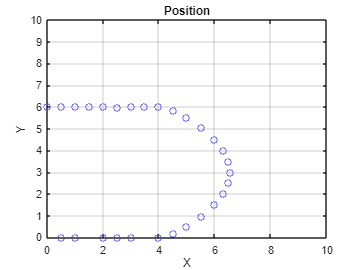

plot(track_info(:, 1), track_info(:, 2),"bo")
title("Position")
axis([0,10,0,10])
xlabel("X")
ylabel("Y")
grid on

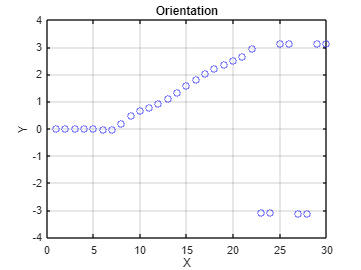

plot(1:length(track_info(:, 3)), track_info(:, 3),"bo")
title("Orientation")
xlabel("X")
ylabel("Y")
grid on

for i = 1:length(track_info)
    if track_info(i, 3) - (-3.14) < 0.2
        track_info(i, 3) = 3.14
    end
end

track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


track_info = 30×3
    0.5000    0.0007    0.0005
    1.0000         0   -0.0039
    1.5000   -0.0022   -0.0024
    2.0000         0    0.0135
    2.4999    0.0080    0.0092
    3.0000    0.0000   -0.0501
    3.4930   -0.0295   -0.0360
    4.0000         0    0.1875
    4.5068    0.1803    0.4757
    5.0000    0.5000    0.6503


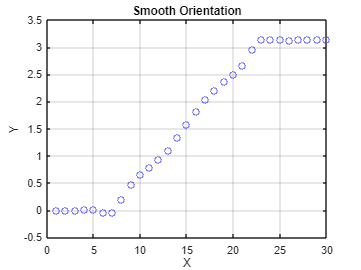

plot(1:length(track_info(:, 3)), track_info(:, 3),"bo")
title("Smooth Orientation")
xlabel("X")
ylabel("Y")
grid on

% save track coordinates in mat file
save("track1.mat","track_info")